clc; clear; close all;

C = 27;
n_values = [50, 75, 100, 125, 150, 175, 200, 225, 250, 275, 300, 400];
d_values = 3:10;

err_values = zeros(length(n_values), length(d_values));

for d_idx=1:length(d_values)
    d = d_values(d_idx);
    
    load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
    load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
    A = double(A);
    Q = double(Q);
    
    for n_idx=1:length(n_values)
        n = n_values(n_idx);
        h = 1/(n-1);
        
        x_mesh = transpose(linspace(0, 1, n));
        fx = f(x_mesh);
        fcont = fcont_gram_blend_S(fx, d, A, Q);
        
        cont_x_mesh = transpose(-C*h:h:1);
        
        fc_coeffs = fft2(fcont)/numel(fcont);
        
        n_cont = n+C;
        n_err = n_cont*5;
        
        x_err_mesh = transpose(linspace(-C*h, 1+h, n_err+1));
        x_err_mesh = x_err_mesh(1:end-1);
        omega_msk = x_err_mesh <= 1 & x_err_mesh >= 0;
        
        shift_vector = exp(-1i*2*pi*(floor(n_cont/2))*transpose(0:(n_err-1))/n_err);
        fcont_numeric = real(n_err*ifft(fftshift(fc_coeffs), n_err).*shift_vector);
        
        err(n_idx, d_idx) = max(abs(f(x_err_mesh(omega_msk)) - fcont_numeric(omega_msk)));
    end
end

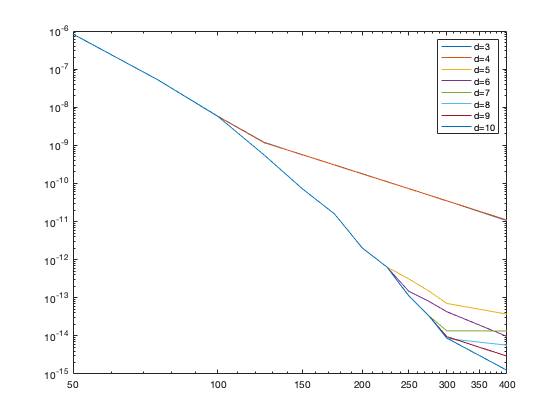

figure;
loglog(n_values, err)
d_legend = cellstr(num2str(d_values', 'd=%-d'));
legend(d_legend)

% very smooth piecewise function being used for testing, vanishes on and
% outside circle of radius 0.56, chosen so 2D-FC for C2 type patches makes
% patch biperiodic
function f_y = f(x)
    f_y = zeros(size(x));
    f_y(x < 0.56) = exp(1./(1/0.56*x(x < 0.56).^2-0.56));
    f_y(x >= 0.56) = 0;
end